motor_parameter_estimation_data = [
    0.00,0.00;
    0.15,0.15;
    0.50,0.49;
    0.64,0.61;
    0.80,0.75;
    0.77,0.73;
    0.88,0.81;
    0.81,0.76;
    0.90,0.84;
    0.82,0.77;
    0.90,0.85;
    0.82,0.77;
    0.93,0.88;
    0.94,0.88;
    0.94,0.86;
    0.93,0.86;
    0.93,0.86;
    0.93,0.86;
    0.92,0.85;
    0.93,0.86;
    0.93,0.86;
    0.93,0.86;
    0.94,0.86;
    0.93,0.86;
    0.93,0.86;
    0.94,0.88;
    0.94,0.86;
    0.94,0.88;
    0.94,0.88;
    0.92,0.85;
    0.93,0.86;
    0.94,0.86;
    0.94,0.88;
    0.94,0.86;
    0.93,0.85;
    0.94,0.86;
    0.93,0.85;
    0.94,0.88;
    0.94,0.86;
    0.95,0.88;
    0.94,0.86;
    0.94,0.86;
    0.94,0.86;
    0.93,0.85;
    0.92,0.85;
    0.92,0.85;
    0.94,0.86;
    0.94,0.88;
    0.93,0.86;
    0.93,0.86;
    0.93,0.88;
    0.94,0.88;
    0.95,0.88;
    0.94,0.88;
    0.95,0.89;
    0.94,0.86;
    0.95,0.88;
    0.94,0.88;
    0.94,0.88;
    0.93,0.86;
    0.93,0.86;
    0.94,0.88;
    0.94,0.88;
    0.94,0.85;
    0.95,0.88;
    0.95,0.88;
    0.94,0.86;
    0.94,0.88;
    0.94,0.86;
    0.94,0.88;
    0.95,0.85;
    0.94,0.86;
    0.94,0.86;
    0.93,0.85;
    0.94,0.86;
    0.94,0.86;
    0.95,0.88;
    0.94,0.88;
    0.94,0.85;
    0.94,0.86;
    0.95,0.86;
    0.95,0.88;
    0.95,0.88;
    0.95,0.89;
    0.94,0.88;
    0.94,0.86;
    0.95,0.89;
    0.95,0.89;
    0.95,0.89;
    0.92,0.86;
    0.94,0.89;
    0.95,0.89;
    0.95,0.89;
    0.95,0.90;
    0.95,0.89;
    0.94,0.89;
    0.95,0.89;
    0.94,0.88;
    0.95,0.88;
    0.95,0.88;
    0.94,0.88;
    0.95,0.86;
    0.95,0.88;
    0.93,0.85;
    0.94,0.86;
    0.95,0.86;
    0.94,0.86;
    0.95,0.86;
    0.94,0.86;
    0.94,0.88;
    0.95,0.88;
    0.95,0.86;
    0.97,0.86;
    0.95,0.86;
    0.94,0.86;
    0.94,0.88;
    0.94,0.88;
    0.94,0.86;
    0.95,0.88;
    0.94,0.85;
    0.94,0.86;
    0.94,0.88;
    0.94,0.86;
    0.95,0.88;
    0.94,0.88;
    0.95,0.88;
    0.95,0.89;
    0.94,0.88;
    0.94,0.86;
    0.94,0.88;
    0.95,0.88;
    0.95,0.89;
    0.95,0.89;
    0.93,0.85;
    0.94,0.88;
    0.94,0.88;
    0.94,0.88;
    0.95,0.89;
    0.97,0.89;
    0.95,0.88;
    0.95,0.89;
    ];

motorL = motor_parameter_estimation_data(:,1);
motorR = motor_parameter_estimation_data(:,2);
time = linspace(0, 3000, 150);
time = time(1:141)';

transient_motorR = motorR(1:25);
transient_motorL = motorL(1:25);
steady_motorR = motorR(25:end);
steady_motorL = motorL(25:end);
transient_t = time(1:25);
steady_t = time(25:end);


figure
clf
hold on
time_s = time/1000;
plot(time_s, motorL, 'b.')
plot(time_s, motorR, 'r.')

% analytical function in time domain
syms a b s
func = (a/b) / ((s + 1/b) * (s/300)); % step response magnitude: 300
fit = simplify(ilaplace(func))

$$fit = 300\,a-300\,a\,{\mathrm{e}}^{-\frac{t}{b}}$$

% using cftool instead
ar =  0.8701;
br = 18.56;
fit_num_r = ar*(1-exp(-br*time_s))

fit_num_r =          0
    0.2713
    0.4580
    0.5865
    0.6749
    0.7358
    0.7777
    0.8065
    0.8263
    0.8400


plot(time_s, fit_num_r, "linewidth",1)

al =   0.9405;
bl = 17.48;
fit_num_l = al*(1-exp(-bl*time_s))

fit_num_l =          0
    0.2790
    0.4753
    0.6133
    0.7104
    0.7786
    0.8267
    0.8604
    0.8842
    0.9009


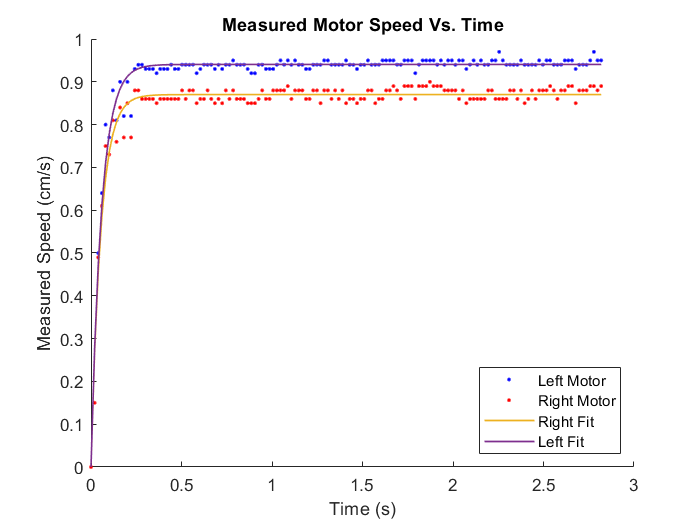

plot(time_s, fit_num_l, "linewidth",1)

ylabel("Measured Speed (cm/s)")
xlabel("Time (s)")
legend("Left Motor", "Right Motor", "Right Fit","Left Fit", 'Location', 'southeast')
title("Measured Motor Speed Vs. Time")


al/300

ans = 0.0031

ar/300

ans = 0.0029